# Hands-On: Estimation of the Static Response Curve of Level Sensors

## Introduction

### What is the static response of a sensor?

The static response of a sensor can be determined by assuming that the sensor input is constant and by ignoring the sensor dynamics. The resulting static response map characterizes the output of the sensor after all transients have settled and the output has converged to a steady-state response.

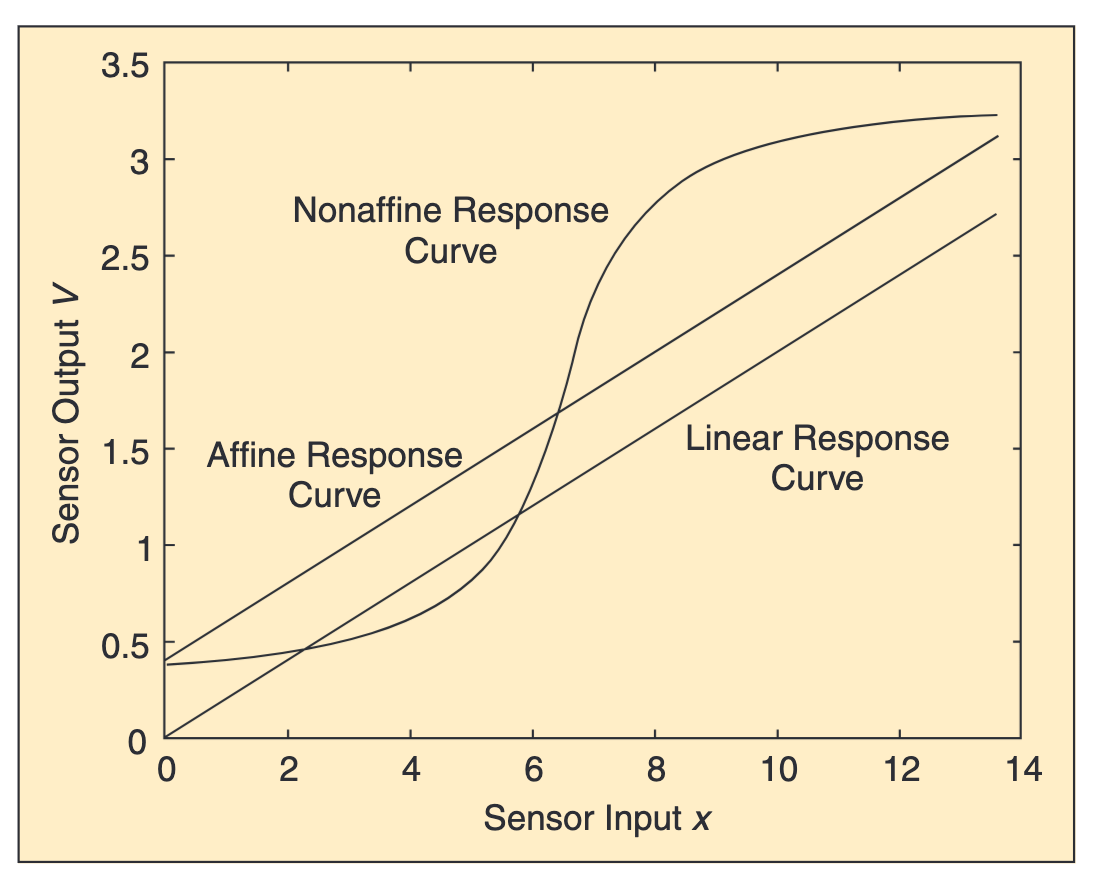

Examples fo static sensor response curves (excerp from [1]).

clear
close all
clc

## An Experiment: Static Response Curve of a Piezoresistive Pressure Sensor

We want to calibrate the level sensors of a Three-Tank-System 

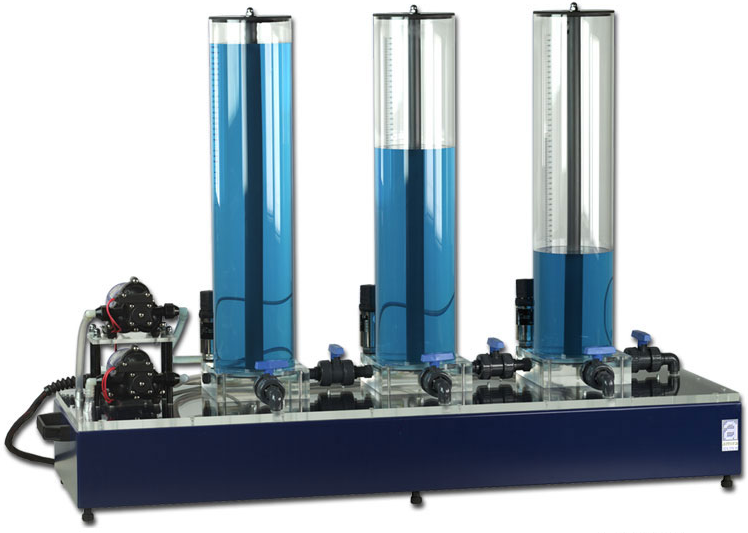

Fig. 1: The Three-Tank-System

These sensors are piezo-resistive pressure sensors, mounted beside the top of each of the three tanks

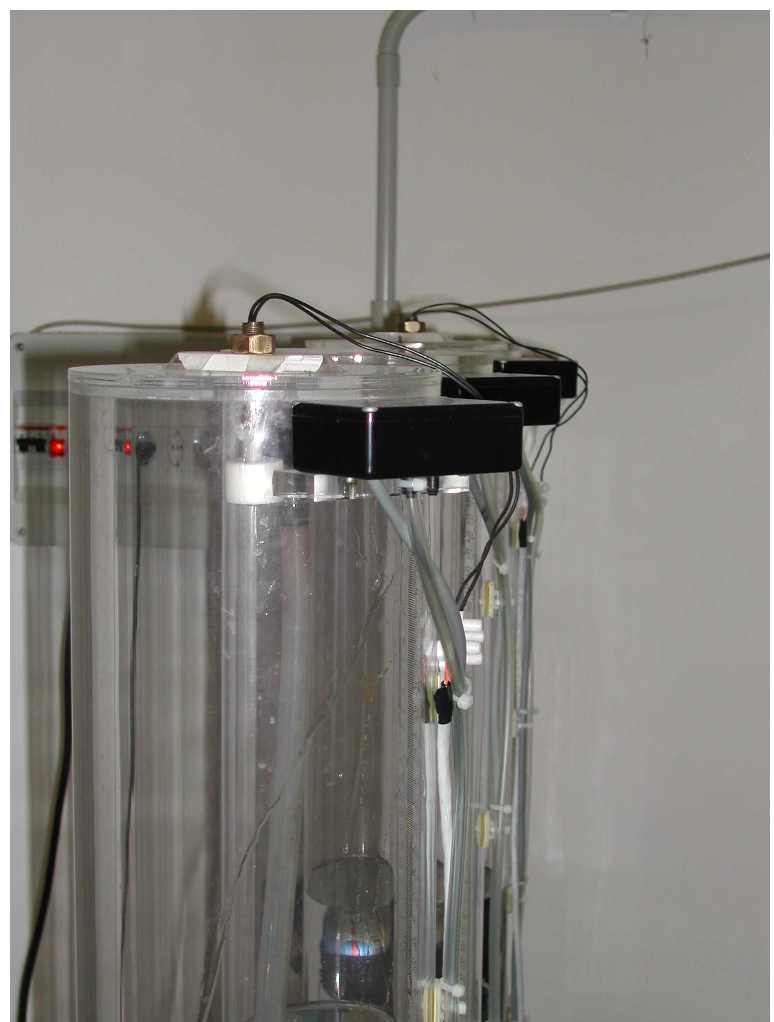 

Fig. 2: A piezoresistive sensor. Note the transparent tube that connects the sensor with the bottom of the cylinder and reports the pressure acting on the bottom of the tank to the sensor.  Note also the white nozzle, used to detect atmospheric pressure and subtract the contribution of air pressure, so that the device only detects the hydrostatic pressure due to the liquid in the tank.

During an experiment to calibrate the level sensors, we collected the following data from one of the level sensors: at predetermined liquid levels in the tank, the voltages provided by the sensor were acquired. The data are shown in the table:


$$\matrix{
\text{liquid level [mm]}    	& \text{voltage [V]} \cr
49 & 	9.74 \cr
98 & 	8.37 \cr
137 & 	7.27 \cr
203 & 	5.43 \cr
305 & 	2.54 \cr
397 & 	-0.05 \cr
504 & 	-2.98 \cr
576 & 	-5.02 \cr
499 & 	-2.91 \cr
402 & 	-0.23 \cr
305 & 	2.50 \cr
197 & 	5.50 \cr
98 & 	8.25 \cr
54 & 	9.51 \cr
}$$
  

Table (1): the preselected liquid levels and the corresponding voltage values, acquired using the sensor.

liquid_L = [49; 98; 137; 203; 305; 397; 504; ...
            576; 499; 402; 305; 197; 98; 54]; % levels [mm]
sensor_V = [9.74; 8.37; 7.27; 5.43; 2.54; -0.05;...
             -2.98; -5.02; -2.91; -0.23; 2.50; 5.50; 8.25; 9.51]; 
            % acquired voltage values [V]

Let's plot the raw data in a figure with the voltage on the x-axis and the level on the y-axis; we use a marker to identify each data value.

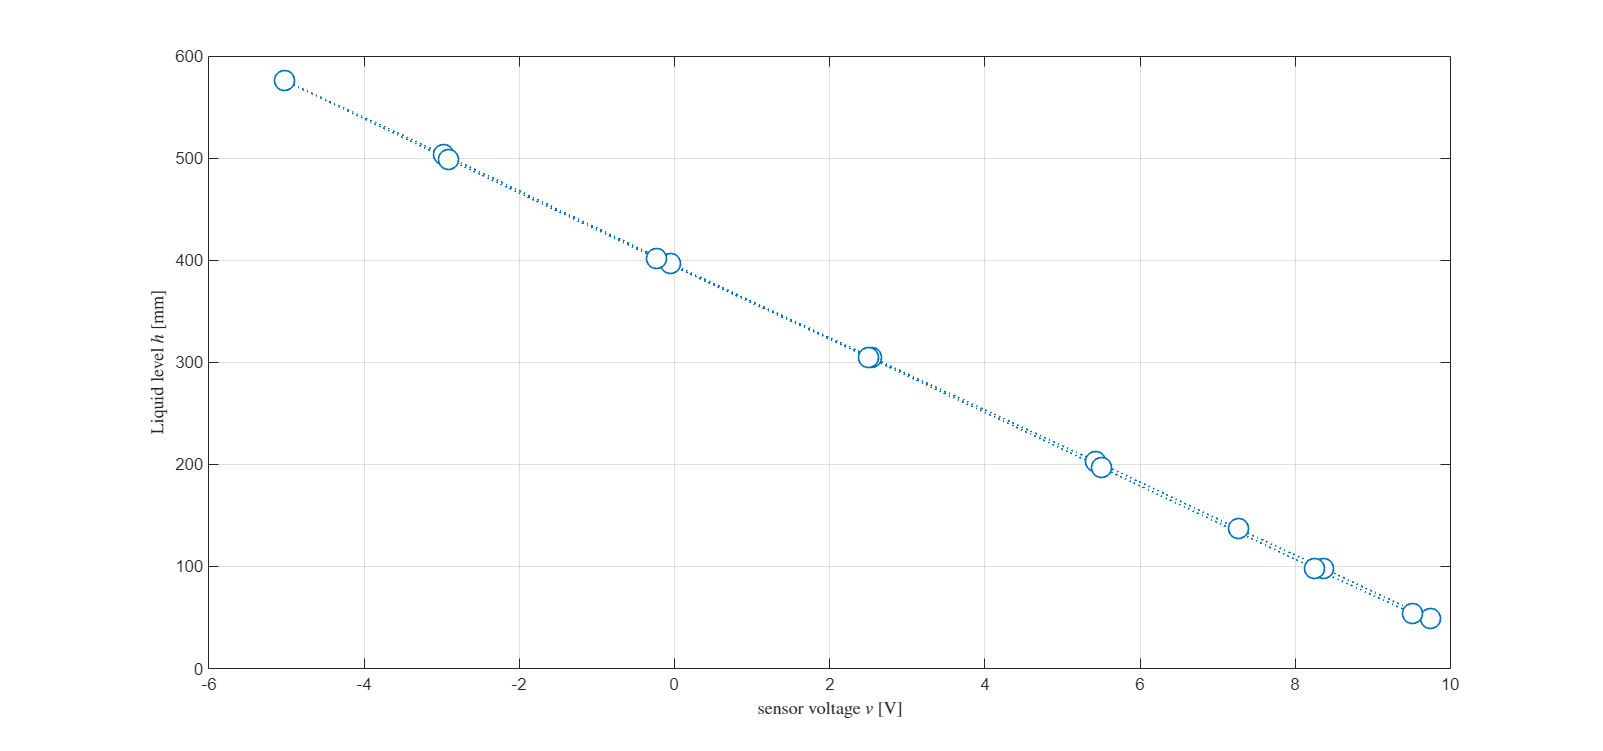

figure('Units','normalized', 'Position', [0.1, 0.1, .9, .75]);
plot(sensor_V, liquid_L,  "LineStyle", ":", "LineWidth", 1, ...
        "Marker","o","MarkerSize", 12, "MarkerEdgeColor","auto", "MarkerFaceColor","auto");
grid on;
ylabel('Liquid level $h$ [mm]','Interpreter','latex');
xlabel('sensor voltage $v$ [V]', 'Interpreter','latex')

The graph looks very similar to that of a linear (affine) function


$$h(t) = \vartheta_1 \, v(t) + \vartheta_2 = 
\left[ \begin{array}{cc} v(t) & 1 \end{array}\right]^{\top} \cdot \left[ 
\begin{array}{c}
\vartheta_1\\
\vartheta_2
\end{array} \right] = \varphi(t)^{\top} \cdot \vartheta$$


## How to Solve the Least-Squares Normal Equations Using MATLAB

devo spiegare la relazione tra un regressore (la tensione) e l'uscita acquisita y l'altezza dell'acqua nel serbatoio.

mi servono 2 parametri (pendenza e intercetta).

Given $N$ observations, we build the following matrices and vectors


$$\Phi_N =
\left [
\begin{array}{c}
\varphi(1)^{\top} \\
\vdots \\
\varphi(N)^{\top}
\end{array}
\right ] 
\quad
\varphi (t)=
\left [
\begin{array}{c}
u_1(t) \\
\vdots \\
u_q(t)
\end{array}
\right ]
\qquad \vartheta =
\left [
\begin{array}{c}
\vartheta_1 \\
\vdots \\
\vartheta_q
\end{array}
\right ] 
\qquad Y_{N} =
\left [
\begin{array}{c}
y(1) \\
\vdots \\
y(N)
\end{array}
\right ]
$$


Now rewrite the regression problem in a compact form as    (equazione vettoriale da cui si parte per arrivare a eq normali)


$$\Phi_{N}\cdot \vartheta = Y_{N}$$


To obtain the *LS normal equations* in compact form, simply multiply both terms of this expression to the left using the transposed matrix $\Phi_N^{\top}$:


$$\Phi_N^{\top} \, \Phi_N\,\vartheta = \Phi_N^{\top} \, Y_{N}$$


### Remark

Verify that


$$\Phi_N^{\top} \, \Phi_N = \left [ \,\sum_{t=1}^N \,\varphi(t)
\, \varphi(t)^{\top} \, \right ] \;,\qquad \Phi_N^{\top} \, Y_{N} = \left[ \sum_{t=1}^N \,
\varphi(t) \, y(t)  \right]$$


### The Moore-Penrose Pseudo Inverse Matrix

La soluzione ai minimi quadrati sta usando la pseudo matrice inversa di moore-penrose.

If the square matrix $\Phi_N^{\top}\,\Phi_N$ is invertible, then the solution of the LS normal equations becomes 


$$\hat{\vartheta}_{N} = \left( \Phi_N^{\top}\,\Phi_N\right)^{-1}\,\Phi_N\,Y_N \qquad (\star)$$


The matrix $\left( \Phi_N^{\top}\,\Phi_N\right)^{-1}\,\Phi_N$ is called the [**Moore-Penrose pseudo inverse matrix**](https://en.wikipedia.org/wiki/Moore%E2%80%93Penrose_inverse) of $\Phi_N$.

### Solving an LS Problem using MATLAB

Two approaches are available: 

- use the command `pinv()` to find the solution exploiting the Moore-Penrose pseudo inverse matrix. Note that `pinv()` produces the pseudo inverse matrix only. In order to compute the solution of the LS normal equations we have to evaluate Eq. $(\star)$.

- apply the command `mldivide()`, given the matrix $\Phi_N$ and the vector $Y_N$, to compute directly the solution $\hat{\vartheta}_N$. (il comando sta per "divido a sinistra delle matrici" ma basta usare "\" slash)

To have a look on the proposed commands syntax, in the MATLAB Command Window type the commands

Have also a look on the shorcutted command \

#### Important Remark

When the matrix $\Phi_N^{\top}\,\Phi_N$ is invertible both the proposed commands provide a similar answer.

## Exercise

Given the data described above, perform the following steps:

- solve a least squared regression problem to determine a linear static response curve for the sensor;

- plot the resulting curve on the same figure with the raw data.

% your code
liquid_L = [49; 98; 137; 203; 305; 397; 504; ...
            576; 499; 402; 305; 197; 98; 54]; % levels [mm]
sensor_V = [9.74; 8.37; 7.27; 5.43; 2.54; -0.05;...
             -2.98; -5.02; -2.91; -0.23; 2.50; 5.50; 8.25; 9.51]; 

Per partire devo scrivere $\Phi_{N}\cdot \vartheta = Y_{N}$

%FI = [sensor_V]
FI = [sensor_V ones(length(liquid_L),1)]

FI =     9.7400    1.0000
    8.3700    1.0000
    7.2700    1.0000
    5.4300    1.0000
    2.5400    1.0000
   -0.0500    1.0000
   -2.9800    1.0000
   -5.0200    1.0000
   -2.9100    1.0000
   -0.2300    1.0000


ymisurati = liquid_L

ymisurati =     49
    98
   137
   203
   305
   397
   504
   576
   499
   402


x = A\B solves the system of linear equations A*x = B. The matrices A and B must have the same number of rows

x = FI \ ymisurati

x =   -35.7727
  395.5876


Provo a plottare:

figure('Units','normalized', 'Position', [0.1, 0.1, .9, .75]);
hold on;
plot(sensor_V, liquid_L,  "LineStyle", ":", "LineWidth", 1, ...
        "Marker","o","MarkerSize", 12, "MarkerEdgeColor","auto", "MarkerFaceColor","auto");
grid on;
ylabel('Liquid level $h$ [mm]','Interpreter','latex');
xlabel('sensor voltage $v$ [V]', 'Interpreter','latex')
%ascisse = linspace(min(sensor_V),max(sensor_V))
valori_calcolati = x(1) * sensor_V + x(2)

valori_calcolati =    47.1618
   96.1703
  135.5203
  201.3420
  304.7250
  397.3762
  502.1902
  575.1664
  499.6861
  403.8153


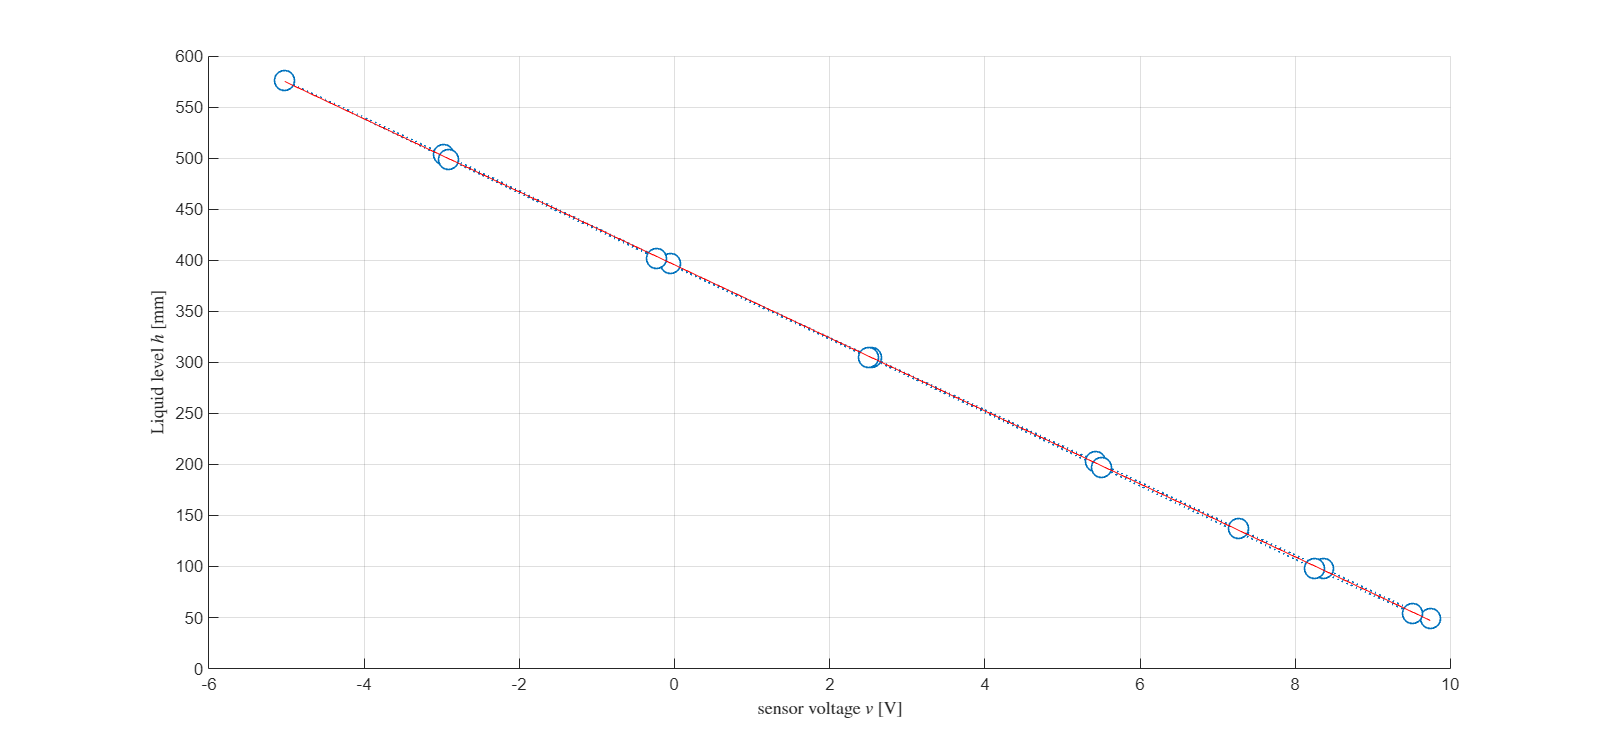

plot(sensor_V,valori_calcolati, "red")
hold off;

%calcolo l'errore
errori = valori_calcolati - ymisurati

errori =    -1.8382
   -1.8297
   -1.4797
   -1.6580
   -0.2750
    0.3762
   -1.8098
   -0.8336
    0.6861
    1.8153


mean(errori)

ans = -4.0602e-14

var(errori)

ans = 2.4869

## References

[1] D. S. Bernstein, "Sensor performance specifications," in *IEEE Control Systems Magazine*, vol. 21, no. 4, pp. 9-18, Aug. 2001, doi: 10.1109/37.939939.